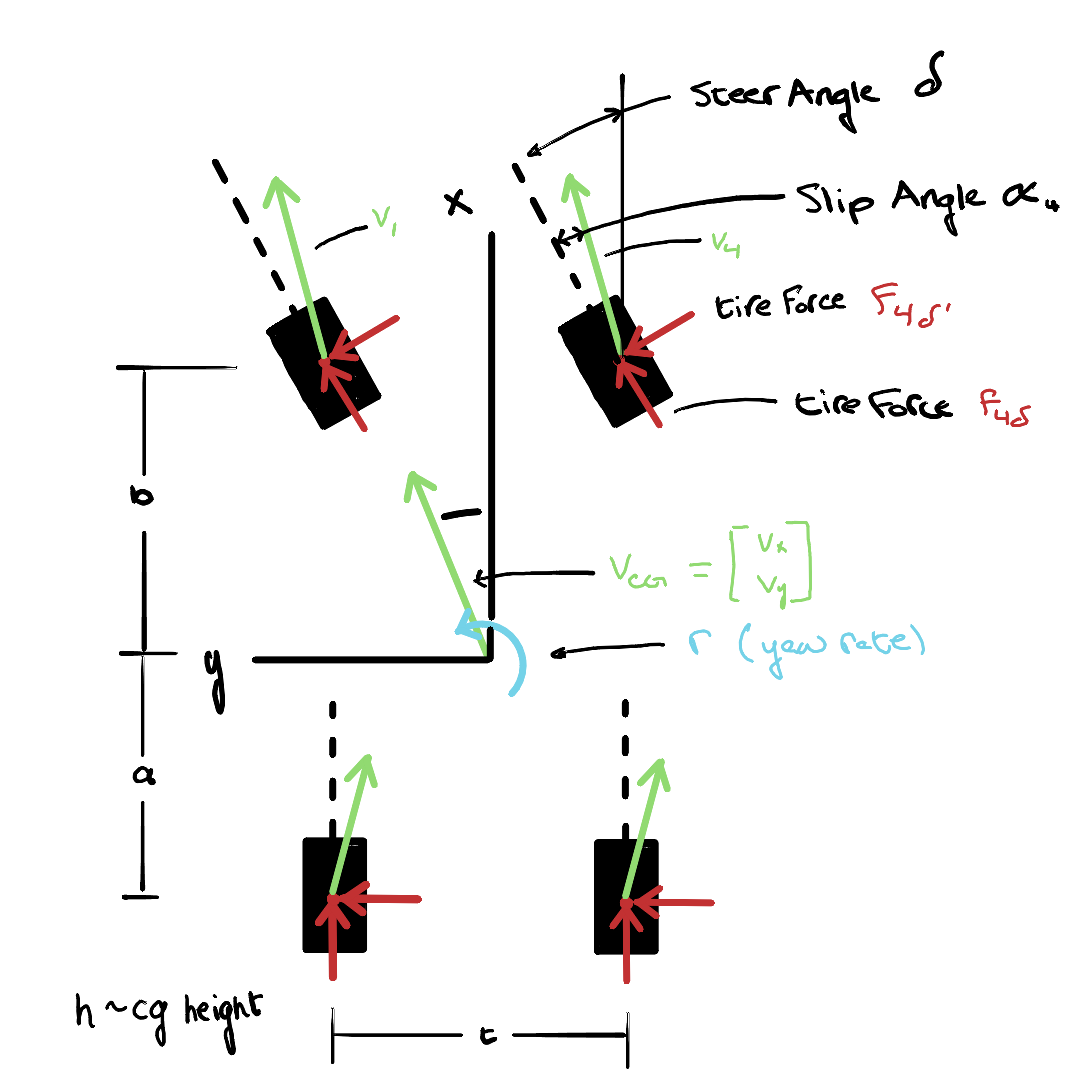

%clear all
%Steering Angle, Slip Angles, wheel radius
syms delta r_wheel
%Body Frame Velocities
syms v_cg v_x v_y r
%Wheel Center Velocities (in the wheel frame)
syms wc_1_vx wc_1_vy wc_2_vx wc_2_vy wc_3_vx wc_3_vy wc_4_vx wc_4_vy
%Wheel Center Acceleration (in the wheel frame)
syms wc_1_ax wc_1_ay wc_2_ax wc_2_ay wc_3_ax wc_3_ay wc_4_ax wc_4_ay

wc_1_v = [wc_1_vx wc_1_vy]; wc_2_v = [wc_2_vx wc_2_vy];
wc_3_v = [wc_3_vx wc_3_vy]; wc_4_v = [wc_4_vx wc_4_vy];
%Wheel rotational velocity
syms omega_1 omega_2 omega_3 omega_4
%Wheel rotational acceleration
syms omega_dot_1 omega_dot_2 omega_dot_3 omega_dot_4
%Wheel Center locations in Body Frame
syms wc_1 wc_1_x wc_1_y wc_2 wc_2_x wc_2_y wc_3 wc_3_x wc_3_y wc_4 wc_4_x wc_4_y
%Location of COM from wheel contact patches, trackwidth
syms a b h t

BodyFrameWheelLocations = [
wc_1_x == b; wc_1_y == t/2;
wc_2_x == -a; wc_2_y == t/2;
wc_3_x == -a; wc_3_y == -t/2;
wc_4_x == b; wc_4_y == -t/2;
]

$$BodyFrameWheelLocations = \left(\begin{array}{c} {\mathrm{wc}}_{1,x}=b\\ {\mathrm{wc}}_{1,y}=\frac{t}{2}\\ {\mathrm{wc}}_{2,x}=-a\\ {\mathrm{wc}}_{2,y}=\frac{t}{2}\\ {\mathrm{wc}}_{3,x}=-a\\ {\mathrm{wc}}_{3,y}=-\frac{t}{2}\\ {\mathrm{wc}}_{4,x}=b\\ {\mathrm{wc}}_{4,y}=-\frac{t}{2} \end{array}\right)$$


WheelFrameWheelVelocity = [
wc_1_vx == (v_x - (wc_1_y*r))*cos(delta) + (v_y + (wc_1_x*r))*sin(delta)
wc_1_vy == (v_y + (wc_1_x*r))*cos(delta) - (v_x - (wc_1_y*r))*sin(delta)
wc_2_vx == v_x - (wc_2_y*r)
wc_2_vy == v_y + (wc_2_x*r)
wc_3_vx == v_x - (wc_3_y*r)
wc_3_vy == v_y + (wc_3_x*r)
wc_4_vx == (v_x - (wc_4_y*r))*cos(delta) + (v_y + (wc_4_x*r))*sin(delta)
wc_4_vy == (v_y + (wc_4_x*r))*cos(delta) - (v_x - (wc_4_y*r))*sin(delta)
]

$$WheelFrameWheelVelocity = \left(\begin{array}{c} {\mathrm{wc}}_{1,\mathrm{vx}}=\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{1,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{1,x}\right)\\ {\mathrm{wc}}_{1,\mathrm{vy}}=\cos\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{1,x}\right)-\sin\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{1,y}\right)\\ {\mathrm{wc}}_{2,\mathrm{vx}}=v_{x}-r\,{\mathrm{wc}}_{2,y}\\ {\mathrm{wc}}_{2,\mathrm{vy}}=v_{y}+r\,{\mathrm{wc}}_{2,x}\\ {\mathrm{wc}}_{3,\mathrm{vx}}=v_{x}-r\,{\mathrm{wc}}_{3,y}\\ {\mathrm{wc}}_{3,\mathrm{vy}}=v_{y}+r\,{\mathrm{wc}}_{3,x}\\ {\mathrm{wc}}_{4,\mathrm{vx}}=\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{4,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{4,x}\right)\\ {\mathrm{wc}}_{4,\mathrm{vy}}=\cos\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{4,x}\right)-\sin\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{4,y}\right) \end{array}\right)$$


%Body frame accelerations
syms r_dot v_dot_x v_dot_y

WheelFrameWheelAcceleration = [
wc_1_ax == v_dot_x - (wc_1_y*r_dot)
wc_1_ay == v_dot_y + (wc_1_x*r_dot)
]

$$WheelFrameWheelAcceleration = \left(\begin{array}{c} {\mathrm{wc}}_{1,\mathrm{ax}}={\dot{v}}_{x}-\dot{r}\,{\mathrm{wc}}_{1,y}\\ {\mathrm{wc}}_{1,\mathrm{ay}}={\dot{v}}_{y}+\dot{r}\,{\mathrm{wc}}_{1,x} \end{array}\right)$$

%Longitudinal slip
syms lambda_1 lambda_2 lambda_3 lambda_4

ZeroLongSlipFront = [
omega_1 == wc_1_vx / r_wheel
omega_4 == wc_4_vx / r_wheel
omega_dot_1 == wc_1_ax / r_wheel
omega_dot_4 == wc_4_ax / r_wheel
];

ZeroLongSlipFront = [
subs(ZeroLongSlipFront, lhs(WheelFrameWheelVelocity), rhs(WheelFrameWheelVelocity))
]

$$ZeroLongSlipFront = \left(\begin{array}{c} \omega_{1}=\frac{\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{1,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{1,x}\right)}{r_{\mathrm{wheel}}}\\ \omega_{4}=\frac{\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{4,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{4,x}\right)}{r_{\mathrm{wheel}}}\\ {\dot{\omega }}_{1}=\frac{{\mathrm{wc}}_{1,\mathrm{ax}}}{r_{\mathrm{wheel}}}\\ {\dot{\omega }}_{4}=\frac{{\mathrm{wc}}_{4,\mathrm{ax}}}{r_{\mathrm{wheel}}} \end{array}\right)$$

ZeroLongSlipFront = [
subs(ZeroLongSlipFront, lhs(WheelFrameWheelAcceleration), rhs(WheelFrameWheelAcceleration))
]

$$ZeroLongSlipFront = \left(\begin{array}{c} \omega_{1}=\frac{\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{1,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{1,x}\right)}{r_{\mathrm{wheel}}}\\ \omega_{4}=\frac{\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{4,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{4,x}\right)}{r_{\mathrm{wheel}}}\\ {\dot{\omega }}_{1}=\frac{{\dot{v}}_{x}-\dot{r}\,{\mathrm{wc}}_{1,y}}{r_{\mathrm{wheel}}}\\ {\dot{\omega }}_{4}=\frac{{\mathrm{wc}}_{4,\mathrm{ax}}}{r_{\mathrm{wheel}}} \end{array}\right)$$


%Be careful of divide by zero here, might need max("",1e-6) in den
%also might need abs(wc_4_vx)
LongitudinalSlip = [
lambda_1 == ((omega_1*r_wheel - wc_1_vx)/abs(wc_1_vx))
lambda_2 == ((omega_2*r_wheel - wc_2_vx)/abs(wc_2_vx))
lambda_3 == ((omega_3*r_wheel - wc_3_vx)/abs(wc_3_vx))
lambda_4 == ((omega_4*r_wheel - wc_4_vx)/abs(wc_4_vx))
];

LongitudinalSlip = [
subs(LongitudinalSlip, lhs(ZeroLongSlipFront), rhs(ZeroLongSlipFront))
];
LongitudinalSlip = [
subs(LongitudinalSlip, lhs(WheelFrameWheelVelocity), rhs(WheelFrameWheelVelocity))
]

$$LongitudinalSlip = \left(\begin{array}{c} \lambda_{1}=0\\ \lambda_{2}=\frac{\omega_{2}\,r_{\mathrm{wheel}}-v_{x}+r\,{\mathrm{wc}}_{2,y}}{\left|v_{x}-r\,{\mathrm{wc}}_{2,y}\right|}\\ \lambda_{3}=\frac{\omega_{3}\,r_{\mathrm{wheel}}-v_{x}+r\,{\mathrm{wc}}_{3,y}}{\left|v_{x}-r\,{\mathrm{wc}}_{3,y}\right|}\\ \lambda_{4}=0 \end{array}\right)$$


%Angular slip
syms alpha_1 alpha_2 alpha_3 alpha_4

LateralSlipAngle = [
alpha_1 == atan(wc_1_vy/wc_1_vx)
alpha_2 == atan(wc_2_vy/wc_2_vx)
alpha_3 == atan(wc_3_vy/wc_3_vx)
alpha_4 == atan(wc_4_vy/wc_4_vx)
]

$$LateralSlipAngle = \left(\begin{array}{c} \alpha_{1}=\mathrm{atan}\left(\frac{{\mathrm{wc}}_{1,\mathrm{vy}}}{{\mathrm{wc}}_{1,\mathrm{vx}}}\right)\\ \alpha_{2}=\mathrm{atan}\left(\frac{{\mathrm{wc}}_{2,\mathrm{vy}}}{{\mathrm{wc}}_{2,\mathrm{vx}}}\right)\\ \alpha_{3}=\mathrm{atan}\left(\frac{{\mathrm{wc}}_{3,\mathrm{vy}}}{{\mathrm{wc}}_{3,\mathrm{vx}}}\right)\\ \alpha_{4}=\mathrm{atan}\left(\frac{{\mathrm{wc}}_{4,\mathrm{vy}}}{{\mathrm{wc}}_{4,\mathrm{vx}}}\right) \end{array}\right)$$


LateralSlipAngle = [
subs(LateralSlipAngle, lhs(WheelFrameWheelVelocity), rhs(WheelFrameWheelVelocity))
]

$$LateralSlipAngle = \left(\begin{array}{c} \alpha_{1}=\mathrm{atan}\left(\frac{\cos\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{1,x}\right)-\sin\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{1,y}\right)}{\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{1,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{1,x}\right)}\right)\\ \alpha_{2}=\mathrm{atan}\left(\frac{v_{y}+r\,{\mathrm{wc}}_{2,x}}{v_{x}-r\,{\mathrm{wc}}_{2,y}}\right)\\ \alpha_{3}=\mathrm{atan}\left(\frac{v_{y}+r\,{\mathrm{wc}}_{3,x}}{v_{x}-r\,{\mathrm{wc}}_{3,y}}\right)\\ \alpha_{4}=\mathrm{atan}\left(\frac{\cos\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{4,x}\right)-\sin\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{4,y}\right)}{\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{4,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{4,x}\right)}\right) \end{array}\right)$$


%Wheel forces
syms F_1_delta F_1_delta_prime F_2_delta F_2_delta_prime F_3_delta F_3_delta_prime F_4_delta F_4_delta_prime
%Wheel forces in body frame
syms F_1_x F_1_y F_2_x F_2_y F_3_x F_3_y F_4_x F_4_y M_1 M_2 M_3 M_4
%Net body frame forces
syms F_x F_y M_z

WheelForceEquations = [
F_1_x == F_1_delta*cos(delta) - F_1_delta_prime*sin(delta)
F_1_y == F_1_delta*sin(delta) + F_1_delta_prime*cos(delta)
F_2_x == F_2_delta
F_2_y == F_2_delta_prime
F_3_x == F_3_delta
F_3_y == F_3_delta_prime
F_4_x == F_4_delta*cos(delta) - F_4_delta_prime*sin(delta)
F_4_y == F_4_delta*sin(delta) + F_4_delta_prime*cos(delta)
]

$$WheelForceEquations = \left(\begin{array}{c} F_{1,x}=F_{1,\delta }\,\cos\left(\delta \right)-F_{1,\delta^{\prime }}\,\sin\left(\delta \right)\\ F_{1,y}=F_{1,\delta^{\prime }}\,\cos\left(\delta \right)+F_{1,\delta }\,\sin\left(\delta \right)\\ F_{2,x}=F_{2,\delta }\\ F_{2,y}=F_{2,\delta^{\prime }}\\ F_{3,x}=F_{3,\delta }\\ F_{3,y}=F_{3,\delta^{\prime }}\\ F_{4,x}=F_{4,\delta }\,\cos\left(\delta \right)-F_{4,\delta^{\prime }}\,\sin\left(\delta \right)\\ F_{4,y}=F_{4,\delta^{\prime }}\,\cos\left(\delta \right)+F_{4,\delta }\,\sin\left(\delta \right) \end{array}\right)$$


% Drag Force (assumed x direction only, no moments)
syms F_drag_x F_drag_y C_drag rho_air A_frontal A_side

DragForceEquations = [
F_drag_x == 0.5*C_drag*rho_air*v_x^2*A_frontal;
F_drag_y == 0.5*C_drag*rho_air*v_y^2*A_side
]

$$DragForceEquations = \left(\begin{array}{c} F_{\mathrm{drag},x}=\frac{A_{\mathrm{frontal}}\,C_{\mathrm{drag}}\,\rho_{\mathrm{air}}\,{v_{x}}^{2}}{2}\\ F_{\mathrm{drag},y}=\frac{A_{\mathrm{side}}\,C_{\mathrm{drag}}\,\rho_{\mathrm{air}}\,{v_{y}}^{2}}{2} \end{array}\right)$$


% Calculate net forces in the body frame
BodyFrameForceEquations = [
F_x == F_1_x + F_2_x + F_3_x + F_4_x - F_drag_x;
F_y == F_1_y + F_2_y + F_3_y + F_4_y - F_drag_y;
];

BodyFrameForceEquations = [
subs(BodyFrameForceEquations, ...
    [lhs(WheelForceEquations); lhs(DragForceEquations)], ...
    [rhs(WheelForceEquations); rhs(DragForceEquations)])
]

$$BodyFrameForceEquations = \left(\begin{array}{c} F_{x}=-\frac{A_{\mathrm{frontal}}\,C_{\mathrm{drag}}\,\rho_{\mathrm{air}}\,{v_{x}}^{2}}{2}+F_{2,\delta }+F_{3,\delta }+F_{1,\delta }\,\cos\left(\delta \right)+F_{4,\delta }\,\cos\left(\delta \right)-F_{1,\delta^{\prime }}\,\sin\left(\delta \right)-F_{4,\delta^{\prime }}\,\sin\left(\delta \right)\\ F_{y}=-\frac{A_{\mathrm{side}}\,C_{\mathrm{drag}}\,\rho_{\mathrm{air}}\,{v_{y}}^{2}}{2}+F_{2,\delta^{\prime }}+F_{3,\delta^{\prime }}+F_{1,\delta^{\prime }}\,\cos\left(\delta \right)+F_{4,\delta^{\prime }}\,\cos\left(\delta \right)+F_{1,\delta }\,\sin\left(\delta \right)+F_{4,\delta }\,\sin\left(\delta \right) \end{array}\right)$$


% Calculate the net moment about the z-axis
YawMomentEquation = M_z == wc_1_x * F_1_y - wc_1_y * F_1_x + ... 
wc_2_x * F_2_y - wc_2_y * F_2_x + wc_3_x * F_3_y - wc_3_y * F_3_x + wc_4_x * F_4_y - wc_4_y * F_4_x;

YawMomentEquation = M_z == solve(simplify(subs(YawMomentEquation, ...
    lhs(WheelForceEquations), rhs(WheelForceEquations))), M_z)

$$YawMomentEquation = M_{z}=F_{2,\delta^{\prime }}\,{\mathrm{wc}}_{2,x}-F_{3,\delta }\,{\mathrm{wc}}_{3,y}-F_{2,\delta }\,{\mathrm{wc}}_{2,y}+F_{3,\delta^{\prime }}\,{\mathrm{wc}}_{3,x}+{\mathrm{wc}}_{1,x}\,\left(F_{1,\delta^{\prime }}\,\cos\left(\delta \right)+F_{1,\delta }\,\sin\left(\delta \right)\right)-{\mathrm{wc}}_{1,y}\,\left(F_{1,\delta }\,\cos\left(\delta \right)-F_{1,\delta^{\prime }}\,\sin\left(\delta \right)\right)+{\mathrm{wc}}_{4,x}\,\left(F_{4,\delta^{\prime }}\,\cos\left(\delta \right)+F_{4,\delta }\,\sin\left(\delta \right)\right)-{\mathrm{wc}}_{4,y}\,\left(F_{4,\delta }\,\cos\left(\delta \right)-F_{4,\delta^{\prime }}\,\sin\left(\delta \right)\right)$$


%Vehicle Inertias
syms I_zz m_vehicle
% Define the equations of motion for the vehicle
BodyFrameMotionEquations = [
(v_dot_x - v_y*r)*m_vehicle == F_x;
(v_dot_y + v_x*r)*m_vehicle == F_y;
r_dot*I_zz == M_z;
];
BodyFrameMotionEquations = subs(BodyFrameMotionEquations, ...
    [lhs(BodyFrameForceEquations(1)), lhs(BodyFrameForceEquations(2)), lhs(YawMomentEquation)], ...
    [rhs(BodyFrameForceEquations(1)), rhs(BodyFrameForceEquations(2)), rhs(YawMomentEquation)])

$$BodyFrameMotionEquations = \left(\begin{array}{c} m_{\mathrm{vehicle}}\,\left({\dot{v}}_{x}-r\,v_{y}\right)=-\frac{A_{\mathrm{frontal}}\,C_{\mathrm{drag}}\,\rho_{\mathrm{air}}\,{v_{x}}^{2}}{2}+F_{2,\delta }+F_{3,\delta }+F_{1,\delta }\,\cos\left(\delta \right)+F_{4,\delta }\,\cos\left(\delta \right)-F_{1,\delta^{\prime }}\,\sin\left(\delta \right)-F_{4,\delta^{\prime }}\,\sin\left(\delta \right)\\ m_{\mathrm{vehicle}}\,\left({\dot{v}}_{y}+r\,v_{x}\right)=-\frac{A_{\mathrm{side}}\,C_{\mathrm{drag}}\,\rho_{\mathrm{air}}\,{v_{y}}^{2}}{2}+F_{2,\delta^{\prime }}+F_{3,\delta^{\prime }}+F_{1,\delta^{\prime }}\,\cos\left(\delta \right)+F_{4,\delta^{\prime }}\,\cos\left(\delta \right)+F_{1,\delta }\,\sin\left(\delta \right)+F_{4,\delta }\,\sin\left(\delta \right)\\ I_{\mathrm{zz}}\,\dot{r}=F_{2,\delta^{\prime }}\,{\mathrm{wc}}_{2,x}-F_{3,\delta }\,{\mathrm{wc}}_{3,y}-F_{2,\delta }\,{\mathrm{wc}}_{2,y}+F_{3,\delta^{\prime }}\,{\mathrm{wc}}_{3,x}+{\mathrm{wc}}_{1,x}\,\left(F_{1,\delta^{\prime }}\,\cos\left(\delta \right)+F_{1,\delta }\,\sin\left(\delta \right)\right)-{\mathrm{wc}}_{1,y}\,\left(F_{1,\delta }\,\cos\left(\delta \right)-F_{1,\delta^{\prime }}\,\sin\left(\delta \right)\right)+{\mathrm{wc}}_{4,x}\,\left(F_{4,\delta^{\prime }}\,\cos\left(\delta \right)+F_{4,\delta }\,\sin\left(\delta \right)\right)-{\mathrm{wc}}_{4,y}\,\left(F_{4,\delta }\,\cos\left(\delta \right)-F_{4,\delta^{\prime }}\,\sin\left(\delta \right)\right) \end{array}\right)$$


%Wheel normal forces using steady state long. and lat. load transfer
%Approximated distribution of roll moment reactive forces between front & rear axle
%lambda_front = ~0.6 sports car understeer, ~0.4 sedan
syms F_z1 F_z2 F_z3 F_z4 lambda_front lambda_rear
syms F_z1_static F_z2_static F_z3_static F_z4_static
syms F_LongitudinalTransfer F_FrontLateralTransfer F_RearLateralTransfer
RollMomentDistribution = [
lambda_front == 0.6
lambda_rear == 1 - lambda_front
]

$$RollMomentDistribution = \left(\begin{array}{c} \lambda_{\mathrm{front}}=\frac{3}{5}\\ \lambda_{\mathrm{rear}}=1-\lambda_{\mathrm{front}} \end{array}\right)$$


StaticNormalForce = [
F_z1_static == m_vehicle*9.81*a / (2*(a+b))
F_z2_static == m_vehicle*9.81*b / (2*(a+b))
F_z3_static == m_vehicle*9.81*b / (2*(a+b))
F_z4_static == m_vehicle*9.81*a / (2*(a+b))
]

$$StaticNormalForce = \left(\begin{array}{c} F_{\mathrm{z1},\mathrm{static}}=\frac{981\,a\,m_{\mathrm{vehicle}}}{100\,\left(2\,a+2\,b\right)}\\ F_{\mathrm{z2},\mathrm{static}}=\frac{981\,b\,m_{\mathrm{vehicle}}}{100\,\left(2\,a+2\,b\right)}\\ F_{\mathrm{z3},\mathrm{static}}=\frac{981\,b\,m_{\mathrm{vehicle}}}{100\,\left(2\,a+2\,b\right)}\\ F_{\mathrm{z4},\mathrm{static}}=\frac{981\,a\,m_{\mathrm{vehicle}}}{100\,\left(2\,a+2\,b\right)} \end{array}\right)$$

%Acceleration & left turning loads the right rear (3)
LoadTransfer = [
F_LongitudinalTransfer == m_vehicle*v_dot_x*h/(a+b)
F_FrontLateralTransfer == lambda_front*(m_vehicle*v_dot_y*h/t)
F_RearLateralTransfer == lambda_rear*(m_vehicle*v_dot_y*h/t)
]

$$LoadTransfer = \left(\begin{array}{c} F_{\mathrm{LongitudinalTransfer}}=\frac{h\,m_{\mathrm{vehicle}}\,{\dot{v}}_{x}}{a+b}\\ F_{\mathrm{FrontLateralTransfer}}=\frac{h\,\lambda_{\mathrm{front}}\,m_{\mathrm{vehicle}}\,{\dot{v}}_{y}}{t}\\ F_{\mathrm{RearLateralTransfer}}=\frac{h\,\lambda_{\mathrm{rear}}\,m_{\mathrm{vehicle}}\,{\dot{v}}_{y}}{t} \end{array}\right)$$


LoadTransfer = [
subs(LoadTransfer,lhs(RollMomentDistribution),rhs(RollMomentDistribution))
]

$$LoadTransfer = \left(\begin{array}{c} F_{\mathrm{LongitudinalTransfer}}=\frac{h\,m_{\mathrm{vehicle}}\,{\dot{v}}_{x}}{a+b}\\ F_{\mathrm{FrontLateralTransfer}}=\frac{3\,h\,m_{\mathrm{vehicle}}\,{\dot{v}}_{y}}{5\,t}\\ F_{\mathrm{RearLateralTransfer}}=-\frac{h\,m_{\mathrm{vehicle}}\,{\dot{v}}_{y}\,\left(\lambda_{\mathrm{front}}-1\right)}{t} \end{array}\right)$$

%NormForce = static + long_transfer + lambda*lat_transfer
NormalForce = [
F_z1 == F_z1_static - F_LongitudinalTransfer - F_FrontLateralTransfer;
F_z2 == F_z1_static + F_LongitudinalTransfer - F_RearLateralTransfer;
F_z3 == F_z1_static + F_LongitudinalTransfer + F_RearLateralTransfer;
F_z4 == F_z1_static - F_LongitudinalTransfer + F_FrontLateralTransfer
]

$$NormalForce = \left(\begin{array}{c} F_{\mathrm{z1}}=F_{\mathrm{z1},\mathrm{static}}-F_{\mathrm{LongitudinalTransfer}}-F_{\mathrm{FrontLateralTransfer}}\\ F_{\mathrm{z2}}=F_{\mathrm{LongitudinalTransfer}}-F_{\mathrm{RearLateralTransfer}}+F_{\mathrm{z1},\mathrm{static}}\\ F_{\mathrm{z3}}=F_{\mathrm{LongitudinalTransfer}}+F_{\mathrm{RearLateralTransfer}}+F_{\mathrm{z1},\mathrm{static}}\\ F_{\mathrm{z4}}=F_{\mathrm{FrontLateralTransfer}}-F_{\mathrm{LongitudinalTransfer}}+F_{\mathrm{z1},\mathrm{static}} \end{array}\right)$$

NormalForce = [
subs(NormalForce, lhs(StaticNormalForce), rhs(StaticNormalForce))
]

$$NormalForce = \begin{array}{l} \left(\begin{array}{c} F_{\mathrm{z1}}=\sigma_{1}-F_{\mathrm{LongitudinalTransfer}}-F_{\mathrm{FrontLateralTransfer}}\\ F_{\mathrm{z2}}=F_{\mathrm{LongitudinalTransfer}}-F_{\mathrm{RearLateralTransfer}}+\sigma_{1}\\ F_{\mathrm{z3}}=F_{\mathrm{LongitudinalTransfer}}+F_{\mathrm{RearLateralTransfer}}+\sigma_{1}\\ F_{\mathrm{z4}}=F_{\mathrm{FrontLateralTransfer}}-F_{\mathrm{LongitudinalTransfer}}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,a\,m_{\mathrm{vehicle}}}{100\,\left(2\,a+2\,b\right)} \end{array}$$


NormalForce = [
subs(NormalForce, lhs(LoadTransfer), rhs(LoadTransfer))
]

$$NormalForce = \begin{array}{l} \left(\begin{array}{c} F_{\mathrm{z1}}=\sigma_{1}-\sigma_{2}-\frac{3\,h\,m_{\mathrm{vehicle}}\,{\dot{v}}_{y}}{5\,t}\\ F_{\mathrm{z2}}=\sigma_{1}+\sigma_{2}+\frac{h\,m_{\mathrm{vehicle}}\,{\dot{v}}_{y}\,\left(\lambda_{\mathrm{front}}-1\right)}{t}\\ F_{\mathrm{z3}}=\sigma_{1}+\sigma_{2}-\frac{h\,m_{\mathrm{vehicle}}\,{\dot{v}}_{y}\,\left(\lambda_{\mathrm{front}}-1\right)}{t}\\ F_{\mathrm{z4}}=\sigma_{1}-\sigma_{2}+\frac{3\,h\,m_{\mathrm{vehicle}}\,{\dot{v}}_{y}}{5\,t} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{981\,a\,m_{\mathrm{vehicle}}}{100\,\left(2\,a+2\,b\right)}\\ \sigma_{2}=\frac{h\,m_{\mathrm{vehicle}}\,{\dot{v}}_{x}}{a+b} \end{array}$$


%Power Delivery (total ang. inertias/damping, ang. speed, motor torque)
syms I_1 I_2 I_3 I_4 B_1 B_2 B_3 B_4
syms omega_1 omega_2 omega_3 omega_4 omega_dot_1 omega_dot_2 omega_dot_3 omega_dot_4
syms T_m2 T_m3

PowerTrainEquations = [
-F_1_delta*r_wheel - B_1*omega_1 == I_1*omega_dot_1
T_m2 - F_2_delta*r_wheel - B_2*omega_2 == I_2*omega_dot_2
T_m3 - F_3_delta*r_wheel - B_3*omega_3 == I_3*omega_dot_3
-F_4_delta*r_wheel - B_4*omega_4 == I_4*omega_dot_4
]

$$PowerTrainEquations = \left(\begin{array}{c} -B_{1}\,\omega_{1}-F_{1,\delta }\,r_{\mathrm{wheel}}=I_{1}\,{\dot{\omega }}_{1}\\ T_{\mathrm{m2}}-B_{2}\,\omega_{2}-F_{2,\delta }\,r_{\mathrm{wheel}}=I_{2}\,{\dot{\omega }}_{2}\\ T_{\mathrm{m3}}-B_{3}\,\omega_{3}-F_{3,\delta }\,r_{\mathrm{wheel}}=I_{3}\,{\dot{\omega }}_{3}\\ -B_{4}\,\omega_{4}-F_{4,\delta }\,r_{\mathrm{wheel}}=I_{4}\,{\dot{\omega }}_{4} \end{array}\right)$$


PowerTrainEquations = [
subs(PowerTrainEquations,lhs(ZeroLongSlipFront), rhs(ZeroLongSlipFront))
]

$$PowerTrainEquations = \left(\begin{array}{c} -F_{1,\delta }\,r_{\mathrm{wheel}}-\frac{B_{1}\,\left(\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{1,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{1,x}\right)\right)}{r_{\mathrm{wheel}}}=\frac{I_{1}\,\left({\dot{v}}_{x}-\dot{r}\,{\mathrm{wc}}_{1,y}\right)}{r_{\mathrm{wheel}}}\\ T_{\mathrm{m2}}-B_{2}\,\omega_{2}-F_{2,\delta }\,r_{\mathrm{wheel}}=I_{2}\,{\dot{\omega }}_{2}\\ T_{\mathrm{m3}}-B_{3}\,\omega_{3}-F_{3,\delta }\,r_{\mathrm{wheel}}=I_{3}\,{\dot{\omega }}_{3}\\ -F_{4,\delta }\,r_{\mathrm{wheel}}-\frac{B_{4}\,\left(\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{4,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{4,x}\right)\right)}{r_{\mathrm{wheel}}}=\frac{I_{4}\,{\mathrm{wc}}_{4,\mathrm{ax}}}{r_{\mathrm{wheel}}} \end{array}\right)$$

PowerTrainEquations = [
subs(PowerTrainEquations,lhs(ZeroLongSlipFront), rhs(ZeroLongSlipFront))
]

$$PowerTrainEquations = \left(\begin{array}{c} -F_{1,\delta }\,r_{\mathrm{wheel}}-\frac{B_{1}\,\left(\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{1,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{1,x}\right)\right)}{r_{\mathrm{wheel}}}=\frac{I_{1}\,\left({\dot{v}}_{x}-\dot{r}\,{\mathrm{wc}}_{1,y}\right)}{r_{\mathrm{wheel}}}\\ T_{\mathrm{m2}}-B_{2}\,\omega_{2}-F_{2,\delta }\,r_{\mathrm{wheel}}=I_{2}\,{\dot{\omega }}_{2}\\ T_{\mathrm{m3}}-B_{3}\,\omega_{3}-F_{3,\delta }\,r_{\mathrm{wheel}}=I_{3}\,{\dot{\omega }}_{3}\\ -F_{4,\delta }\,r_{\mathrm{wheel}}-\frac{B_{4}\,\left(\cos\left(\delta \right)\,\left(v_{x}-r\,{\mathrm{wc}}_{4,y}\right)+\sin\left(\delta \right)\,\left(v_{y}+r\,{\mathrm{wc}}_{4,x}\right)\right)}{r_{\mathrm{wheel}}}=\frac{I_{4}\,{\mathrm{wc}}_{4,\mathrm{ax}}}{r_{\mathrm{wheel}}} \end{array}\right)$$



%Pacejka MF, friction coeffs., long. & lat.
syms B_MF_long C_MF_long D_MF_long E_MF_long
syms mu_1_long mu_2_long mu_3_long mu_4_long
syms B_MF_lat C_MF_lat D_MF_lat E_MF_lat mu_lat
syms mu_1_lat mu_2_lat mu_3_lat mu_4_lat
Params_Pacejka = [


]


Params_Pacejka =

     []



%Pacejka MF-based, wheel 1&4 (front wheels) no longitudinal slip
TractiveEquations = [
F_1_delta == solve(PowerTrainEquations(1), F_1_delta)
F_2_delta == mu_2_long*F_z2*sin(C_MF_long*atan(B_MF_long*lambda_2 - E_MF_long*(B_MF_long*lambda_2 - atan(B_MF_long*lambda_2))))
F_3_delta == mu_3_long*F_z3*sin(C_MF_long*atan(B_MF_long*lambda_3 - E_MF_long*(B_MF_long*lambda_3 - atan(B_MF_long*lambda_3))))
F_4_delta == solve(PowerTrainEquations(4), F_4_delta)

F_1_delta_prime == mu_1_lat*F_z1*sin(C_MF_lat*atan(B_MF_lat*alpha_1 - E_MF_lat*(B_MF_lat*alpha_1 - atan(B_MF_lat*alpha_1))))
F_2_delta_prime == mu_2_lat*F_z2*sin(C_MF_lat*atan(B_MF_lat*alpha_2 - E_MF_lat*(B_MF_lat*alpha_2 - atan(B_MF_lat*alpha_2))))
F_3_delta_prime == mu_3_lat*F_z3*sin(C_MF_lat*atan(B_MF_lat*alpha_3 - E_MF_lat*(B_MF_lat*alpha_3 - atan(B_MF_lat*alpha_3))))
F_4_delta_prime == mu_4_lat*F_z4*sin(C_MF_lat*atan(B_MF_lat*alpha_4 - E_MF_lat*(B_MF_lat*alpha_4 - atan(B_MF_lat*alpha_4))))
]


TractiveEquations = [
subs(TractiveEquations, [lhs(LongitudinalSlip), lhs(LateralSlipAngle), lhs(NormalForce)], ...
[rhs(LongitudinalSlip), rhs(LateralSlipAngle), rhs(NormalForce)])
]


%Compilation into State Space

StateVector = [
v_x
v_y
r
omega_2
omega_3
]

$$StateVector = \left(\begin{array}{c} v_{x}\\ v_{y}\\ r\\ \omega_{2}\\ \omega_{3} \end{array}\right)$$


StateVectorDeriv = [
v_dot_x
v_dot_y
r_dot
omega_dot_2
omega_dot_3
]

$$StateVectorDeriv = \left(\begin{array}{c} {\dot{v}}_{x}\\ {\dot{v}}_{y}\\ \dot{r}\\ {\dot{\omega }}_{2}\\ {\dot{\omega }}_{3} \end{array}\right)$$


StateEquations = [
BodyFrameMotionEquations(1)

BodyFrameMotionEquations(2)
BodyFrameMotionEquations(3)
PowerTrainEquations(2)
PowerTrainEquations(3)
]

$$StateEquations = \left(\begin{array}{c} m_{\mathrm{vehicle}}\,\left({\dot{v}}_{x}-r\,v_{y}\right)=-\frac{A_{\mathrm{frontal}}\,C_{\mathrm{drag}}\,\rho_{\mathrm{air}}\,{v_{x}}^{2}}{2}+F_{2,\delta }+F_{3,\delta }+F_{1,\delta }\,\cos\left(\delta \right)+F_{4,\delta }\,\cos\left(\delta \right)-F_{1,\delta^{\prime }}\,\sin\left(\delta \right)-F_{4,\delta^{\prime }}\,\sin\left(\delta \right)\\ m_{\mathrm{vehicle}}\,\left({\dot{v}}_{y}+r\,v_{x}\right)=-\frac{A_{\mathrm{side}}\,C_{\mathrm{drag}}\,\rho_{\mathrm{air}}\,{v_{y}}^{2}}{2}+F_{2,\delta^{\prime }}+F_{3,\delta^{\prime }}+F_{1,\delta^{\prime }}\,\cos\left(\delta \right)+F_{4,\delta^{\prime }}\,\cos\left(\delta \right)+F_{1,\delta }\,\sin\left(\delta \right)+F_{4,\delta }\,\sin\left(\delta \right)\\ I_{\mathrm{zz}}\,\dot{r}=F_{2,\delta^{\prime }}\,{\mathrm{wc}}_{2,x}-F_{3,\delta }\,{\mathrm{wc}}_{3,y}-F_{2,\delta }\,{\mathrm{wc}}_{2,y}+F_{3,\delta^{\prime }}\,{\mathrm{wc}}_{3,x}+{\mathrm{wc}}_{1,x}\,\left(F_{1,\delta^{\prime }}\,\cos\left(\delta \right)+F_{1,\delta }\,\sin\left(\delta \right)\right)-{\mathrm{wc}}_{1,y}\,\left(F_{1,\delta }\,\cos\left(\delta \right)-F_{1,\delta^{\prime }}\,\sin\left(\delta \right)\right)+{\mathrm{wc}}_{4,x}\,\left(F_{4,\delta^{\prime }}\,\cos\left(\delta \right)+F_{4,\delta }\,\sin\left(\delta \right)\right)-{\mathrm{wc}}_{4,y}\,\left(F_{4,\delta }\,\cos\left(\delta \right)-F_{4,\delta^{\prime }}\,\sin\left(\delta \right)\right)\\ T_{\mathrm{m2}}-B_{2}\,\omega_{2}-F_{2,\delta }\,r_{\mathrm{wheel}}=I_{2}\,{\dot{\omega }}_{2}\\ T_{\mathrm{m3}}-B_{3}\,\omega_{3}-F_{3,\delta }\,r_{\mathrm{wheel}}=I_{3}\,{\dot{\omega }}_{3} \end{array}\right)$$


StateEquations = [
subs(StateEquations,lhs(TractiveEquations),rhs(TractiveEquations))
]


StateEquations = [
v_dot_x == solve(StateEquations(1),v_dot_x)
v_dot_y == solve(StateEquations(2),v_dot_y)
r_dot == solve(StateEquations(3),r_dot)
omega_dot_2 == solve(StateEquations(4),omega_dot_2)
omega_dot_3 == solve(StateEquations(5),omega_dot_3)
]


Input = [
T_m2
T_m3
delta
]

$$Input = \left(\begin{array}{c} T_{\mathrm{m2}}\\ T_{\mathrm{m3}}\\ \delta \end{array}\right)$$

$$VehicleParameters = \left(\begin{array}{c} B_{1}\\ B_{4}\\ B_{\mathrm{MF},\mathrm{lat}}\\ B_{\mathrm{MF},\mathrm{long}}\\ C_{\mathrm{MF},\mathrm{lat}}\\ C_{\mathrm{MF},\mathrm{long}}\\ E_{\mathrm{MF},\mathrm{lat}}\\ E_{\mathrm{MF},\mathrm{long}}\\ I_{1}\\ I_{4}\\ I_{\mathrm{zz}}\\ a\\ b\\ h\\ \lambda_{\mathrm{front}}\\ m_{\mathrm{vehicle}}\\ \mu_{1,\mathrm{lat}}\\ \mu_{2,\mathrm{lat}}\\ \mu_{3,\mathrm{lat}}\\ \mu_{4,\mathrm{lat}}\\ \mu_{2,\mathrm{long}}\\ \mu_{3,\mathrm{long}}\\ \dot{r}\\ r_{\mathrm{wheel}}\\ t\\ {\dot{v}}_{x}\\ {\dot{v}}_{y}\\ {\mathrm{wc}}_{1,x}\\ {\mathrm{wc}}_{1,y}\\ {\mathrm{wc}}_{2,x}\\ {\mathrm{wc}}_{2,y}\\ {\mathrm{wc}}_{3,x}\\ {\mathrm{wc}}_{3,y}\\ {\mathrm{wc}}_{4,x}\\ {\mathrm{wc}}_{4,y}\\ {\mathrm{wc}}_{4,\mathrm{ax}} \end{array}\right)$$

jacobian(rhs(StateEquations),StateVector)

%Pacejka Parameter List
    %[B_long, B_lat]
    %[C_long, C_lat]
    %[D_long, D_lat]
    %[E_long, E_lat]
%pacejka_ = [10.5, 9.5; 1.65, 1.25; 1.1*F_z, 1.3*F_z; 0.2, -0.5];

Attempt to solve z = [v_dot_x; v_dot_y; r_dot] algebraically given state vector & input

%syms soln1 soln2 soln3
z = [v_dot_x; v_dot_y; r_dot];

Residual = z - rhs(StateEquations(1:3)) == 0

soln = solve(Residual,z)

soln = struct with fields:
    v_dot_x: -(- 4905*I_zz*a*m_vehicle*mu_2_long*r_wheel^4*t*sin(C_MF_long*atan(E_MF_long*(atan((B_MF_long*(omega_2*r_wheel - v_x + r*wc_2_y))/abs(v_x - r*wc_2_y)) - (B_MF_long*(omega_2*r_wheel - v_x + r*wc_2_y))/abs(v_x - r*wc_2_y)) + (B_MF_long*(omeg…
    v_dot_y: (t*(981*I_zz*a^2*m_vehicle^2*mu_2_lat*r_wheel^4*sin(C_MF_lat*atan(E_MF_lat*(atan(B_MF_lat*atan((v_y + r*wc_2_x)/(v_x - r*wc_2_y))) - B_MF_lat*atan((v_y + r*wc_2_x)/(v_x - r*wc_2_y))) + B_MF_lat*atan((v_y + r*wc_2_x)/(v_x - r*wc_2_y)))) + 9…
      r_dot: (- 4905*a^2*m_vehicle^2*mu_2_long*r_wheel^4*t*wc_2_y*sin(C_MF_long*atan(E_MF_long*(atan((B_MF_long*(omega_2*r_wheel - v_x + r*wc_2_y))/abs(v_x - r*wc_2_y)) - (B_MF_long*(omega_2*r_wheel - v_x + r*wc_2_y))/abs(v_x - r*wc_2_y)) + (B_MF_long*…


%disp
%check = [soln1; soln2; soln3] == solve(Residual,z)

soln.v_dot_x
soln.v_dot_y
soln.r_dot



%Vectorized vehicle params
VehicleParameters = [
B_1
B_2
B_3
B_4
B_MF_lat
B_MF_long
C_MF_lat
C_MF_long
E_MF_lat
E_MF_long
I_1
I_2
I_3
I_4
I_zz
a
b
h
lambda_front
m_vehicle
A_frontal
A_side
C_drag
rho_air
mu_1_lat
mu_2_lat
mu_3_lat
mu_4_lat
mu_2_long
mu_3_long
r_dot
r_wheel
t
v_dot_x
v_dot_y
wc_1_x
wc_1_y
wc_2_x
wc_2_y
wc_3_x
wc_3_y
wc_4_x
wc_4_y
wc_4_ax
]

$$VehicleParameters = \left(\begin{array}{c} B_{1}\\ B_{2}\\ B_{3}\\ B_{4}\\ B_{\mathrm{MF},\mathrm{lat}}\\ B_{\mathrm{MF},\mathrm{long}}\\ C_{\mathrm{MF},\mathrm{lat}}\\ C_{\mathrm{MF},\mathrm{long}}\\ E_{\mathrm{MF},\mathrm{lat}}\\ E_{\mathrm{MF},\mathrm{long}}\\ I_{1}\\ I_{2}\\ I_{3}\\ I_{4}\\ I_{\mathrm{zz}}\\ a\\ b\\ h\\ \lambda_{\mathrm{front}}\\ m_{\mathrm{vehicle}}\\ A_{\mathrm{frontal}}\\ A_{\mathrm{side}}\\ C_{\mathrm{drag}}\\ \rho_{\mathrm{air}}\\ \mu_{1,\mathrm{lat}}\\ \mu_{2,\mathrm{lat}}\\ \mu_{3,\mathrm{lat}}\\ \mu_{4,\mathrm{lat}}\\ \mu_{2,\mathrm{long}}\\ \mu_{3,\mathrm{long}}\\ \dot{r}\\ r_{\mathrm{wheel}}\\ t\\ {\dot{v}}_{x}\\ {\dot{v}}_{y}\\ {\mathrm{wc}}_{1,x}\\ {\mathrm{wc}}_{1,y}\\ {\mathrm{wc}}_{2,x}\\ {\mathrm{wc}}_{2,y}\\ {\mathrm{wc}}_{3,x}\\ {\mathrm{wc}}_{3,y}\\ {\mathrm{wc}}_{4,x}\\ {\mathrm{wc}}_{4,y}\\ {\mathrm{wc}}_{4,\mathrm{ax}} \end{array}\right)$$


%Solves an expression with input 'Vars'. d/dt(x_bar) in this case
%combines Ax+Bu (evaluates this with one function of x & u)
%Takes StateEquations vector of expressions (which symbolically define the
%time deriv of the state vector), and returns symbolic expression vector
%evaluated at StateVector, Input, Params
%d/dt(x_bar) = f_handle(StateVector,Input,VehicleParameters)
f_handle = matlabFunction(rhs(StateEquations),'Vars',{StateVector,Input,VehicleParameters})

f_handle = function_handle with value:
    @(in1,in2,in3)[((cos(in2(3,:)).*((in3(1,:).*(cos(in2(3,:)).*(in1(1,:)-in1(3,:).*in3(37,:))+sin(in2(3,:)).*(in1(2,:)+in1(3,:).*in3(36,:))))./in3(32,:)-(in3(11,:).*in3(31,:).*in3(37,:))./in3(32,:)))./in3(32,:)-in3(20,:).*in1(3,:).*in1(2,:)+(cos(in2(3,:)).*((in3(4,:).*(cos(in2(3,:)).*(in1(1,:)-in1(3,:).*in3(43,:))+sin(in2(3,:)).*(in1(2,:)+in1(3,:).*in3(42,:))))./in3(32,:)+(in3(14,:).*in3(44,:))./in3(32,:)))./in3(32,:)-in3(29,:).*sin(in3(8,:).*atan(in3(10,:).*(atan((in3(6,:).*(-in1(1,:)+in1(4,:).*in3(32,:)+in1(3,:).*in3(39,:)))./abs(in1(1,:)-in1(3,:).*in3(39,:)))-(in3(6,:).*(-in1(1,:)+in1(4,:).*in3(32,:)+in1(3,:).*in3(39,:)))./abs(in1(1,:)-in1(3,:).*in3(39,:)))+(in3(6,:).*(-in1(1,:)+in1(4,:).*in3(32,:)+in1(3,:).*in3(39,:)))./abs(in1(1,:)-in1(3,:).*in3(39,:)))).*((in3(16,:).*in3(20,:).*(9.81e+2./1.0e+2))./(in3(16,:).*2.0+in3(17,:).*2.0)+(in3(18,:).*in3(20,:).*in3(35,:).*(in3(19,:)-1.0))./in3(33,:))-in3(30,:).*sin(in3(8,:).*atan(in3(10,:).*(atan((in

CasADi

import casadi.*


% Symbols/expressions
x = MX.sym('x');
y = MX.sym('y');
z = MX.sym('z');
f = x^2+100*z^2;
g = z+(1-x)^2-y;

nlp = struct;            % NLP declaration
nlp.x = [x;y;z];         % decision vars
nlp.f = f;               % objective
nlp.g = g;               % constraints

% Create solver instance
F = nlpsol('F','ipopt',nlp);

% Solve the problem using a guess
F('x0',[2.5 3.0 0.75],'ubg',0,'lbg',0)

This is Ipopt version 3.14.11, running with linear solver MUMPS 5.4.1.

Number of nonzeros in equality constraint Jacobian...:        3
Number of nonzeros in inequality constraint Jacobian.:        0
Number of nonzeros in Lagrangian Hessian.............:        2

Total number of variables............................:        3
                     variables with only lower bounds:        0
                variables with lower and upper bounds:        0
                     variables with only upper bounds:        0
Total number of equality constraints.................:        1
Total number of inequality constraints...............:        0
        inequality constraints with only lower bounds:        0
   inequality constraints with lower and upper bounds:        0
        inequality constraints with only upper bounds:        0

iter    objective    inf_pr   inf_du lg(mu)  ||d||  lg(rg) alpha_du alpha_pr  ls
   0  6.2500000e+01 0.00e+00 9.00e+01  -1.0 0.00e+00    -  0.00e+00 0.00e+00 

ans = struct with fields:
        f: [1×1 casadi.DM]
        g: [1×1 casadi.DM]
    lam_g: [1×1 casadi.DM]
    lam_p: [0×0 casadi.DM]
    lam_x: [3×1 casadi.DM]
        x: [3×1 casadi.DM]
